# Determine the z-offset of a point cloud relative to a given map

## Read the point cloud data

% Read the map point cloud.
pcMap = removeInvalidPoints(pcread('pcd/data/campus_freiburg.pcd'));
pcMap = pcdownsample(pcMap, 'gridAverage', 0.01);
pcMap = select(pcMap, findPointsInROI(pcMap, [-15, 95; -80, 0; -Inf, +Inf]));

% Read the sensor point cloud.
pcSensor = removeInvalidPoints(pcread('pcd/data/bonirob_campus.pcd'));
pcSensor = pcdownsample(pcSensor, 'gridAverage', 0.01);
tfInit = [quat2rotm([1, -0.009, -0.000, -0.027]), [55.725; -42.839; 0]; 0,0,0,1];
pcSensor = pctransform(pcSensor, ht2affine3d(tfInit));

## Create an elevation map from the map point cloud

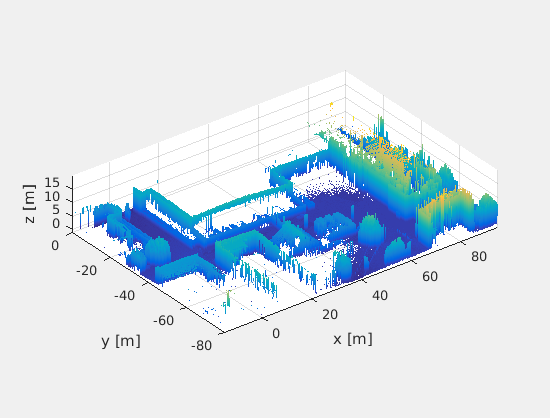

% Create the elevation map and fill the gaps in the map.
em = fillnan(elevationmap(pcMap, 0.05), [5,5]);
em.plot; labelaxes('m'); grid

## Determine the height of the ground plane of the map

% Compute a bit mask that tells below or above which tiles of the elevation map sensor points are located.
mask = em.mask(pcSensor.Location(:,1:2));

% Compute the mean z-coordinate of the lowest 20% of all tiles that are located below of above the point cloud.
zEm = sort(em.elevation(mask));
zMap = mean(zEm(1:round(numel(zEm)*0.2)))

zMap = -0.0601

## Determine the height of the ground plane of the sensor point cloud

% Sort the points in order of their z-coordinate.
zPc = sort(pc.Location(:,3));
zSensor = mean(zPc(1:round(numel(zPc)*0.2)))

zSensor = -1.0335

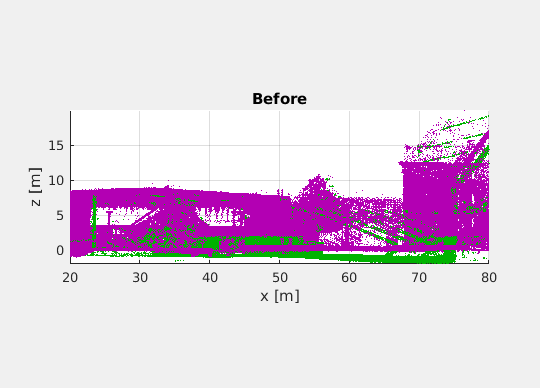

% Plot the original and the corrected scan.
pcSensorCorr = pointCloud(pcSensor.Location + repmat([0,0,zMap-zSensor], pcSensor.Count, 1));
pcshowpair(pcMap, pcSensor); view(0,0); xlim([20,80]); labelaxes('m'); title('Before')

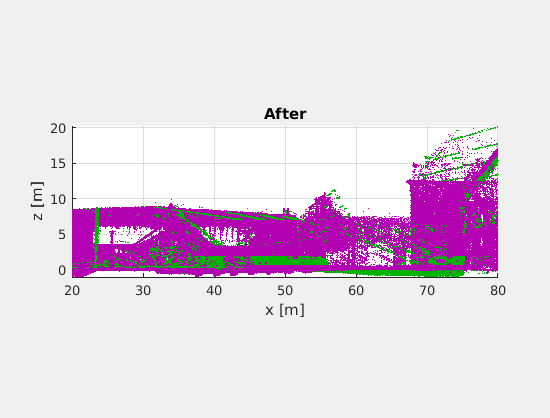

pcshowpair(pcMap, pcSensorCorr); view(0,0); xlim([20,80]); labelaxes('m'); title('After')